## Project Code

This is the pill pusher needs to be solved with 2 vector loops one small one big

clc
clear
% knowns
a =.32;
c =.65;
f = 1.3;
omega2 = 1;%rad/sec
alpha2 = 0;


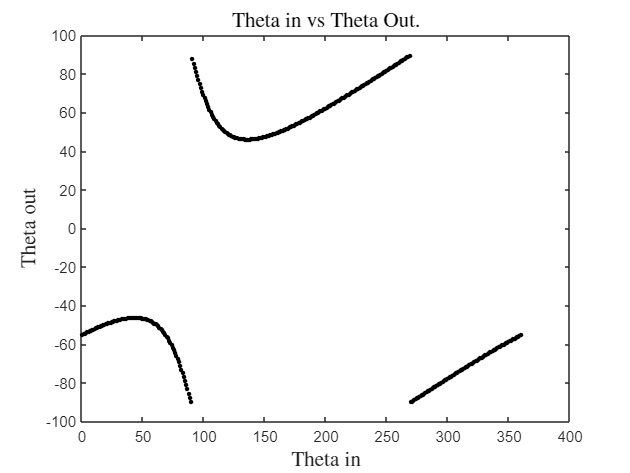

% Position
for i=1:360
    theta2(i) = i;
    theta3(i) = atand((a*sind(theta2(i))-c)/(a*cosd(theta2(i))));
    b(i) = a*cosd(theta2(i))/(cosd(theta3(i)));

    Pax(i) = a*cosd(theta2(i));
    Pay(i) = a*sind(theta2(i))-c;

    Pbx(i) = b(i)*cosd(theta3(i));
    Pby(i) = b(i)*sind(theta3(i));
    
    d(i) = -f/(sind(theta3(i)));
    e(i) = d(i)*cosd(theta3(i));
 
    Pdx(i) = d(i)*cosd(theta3(i));
    Pdy(i) = d(i)*sind(theta3(i));

    Pex(i) = e(i);
    Pey(i) = -f;

end
    fig1=figure();
    axis equal; 
    plot(theta2,theta3,'ko',"LineWidth",2,'MarkerSize',1)
    xlabel('Theta in ','Interpreter',"latex","FontSize",14)
    ylabel('Theta out','Interpreter',"latex","FontSize",14)
    title('Theta in vs Theta Out.','Interpreter',"latex","FontSize",14)

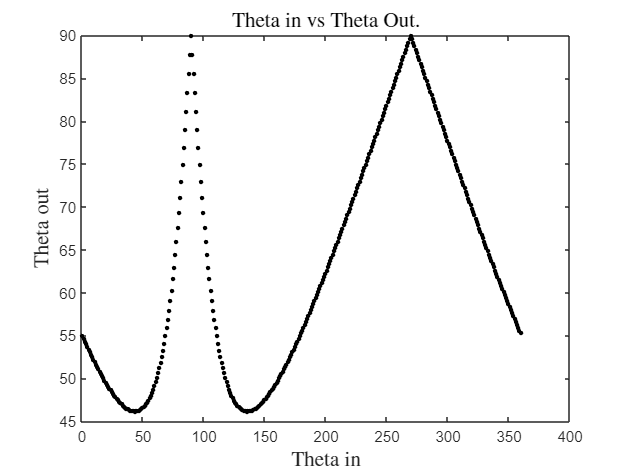

    fig2=figure();
    axis equal; 
    plot(theta2,abs(theta3),'ko',"LineWidth",2,'MarkerSize',1)
    xlabel('Theta in ','Interpreter',"latex","FontSize",14)
    ylabel('Theta out','Interpreter',"latex","FontSize",14)
    title('Theta in vs Theta Out.','Interpreter',"latex","FontSize",14)

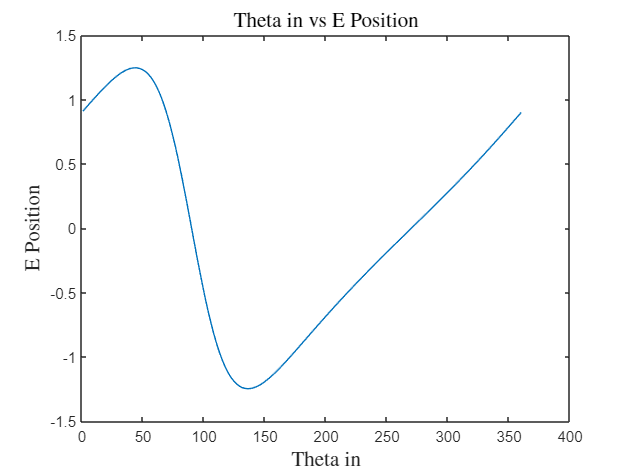

fig3=figure();
    axis ([0 360 -3 3]); 
    plot(theta2,Pex)
    xlabel('Theta in ','Interpreter',"latex","FontSize",14)
    ylabel('E Position','Interpreter',"latex","FontSize",14)
    title('Theta in vs E Position','Interpreter',"latex","FontSize",14)

% Velocity 
for i = 1:360
     A = [cosd(theta3(i)),-b(i)*sind(theta3(i));
        sind(theta3(i)),b(i)*cosd(theta3(i))];

    B = [-a*omega2*sind(theta2(i));
        a*omega2*cosd(theta2(i))];

    X = A\B;

    bdot(i) = X(1,1);
    omega3(i) = X(2,1);

    Vax(i) = -a*omega2*sind(theta2(i));
    Vay(i) = a*omega2*cosd(theta2(i));

    Vbx(i) = bdot(i)*cosd(theta3(i))-b(i)*omega3(i)*sind(theta3(i));
    Vby(i) = bdot(i)*sind(theta3(i))+b(i)*omega3(i)*cosd(theta3(i));

    ddot(i) = (-d(i)*omega3(i)*cosd(theta3(i)))/(sind(theta3(i)));
    edot(i) = ddot(i)*cosd(theta3(i))-d(i)*omega3(i)*sind(theta3(i));

    Vdx(i) = ddot(i)*cosd(theta3(i))-d(i)*omega3(i)*sind(theta3(i));
    Vdy(i) = ddot(i)*sind(theta3(i))+d(i)*omega3(i)*cosd(theta3(i));% pretty much zero

    Vex(i) = edot(i);
    Vey(i) = 0;
end

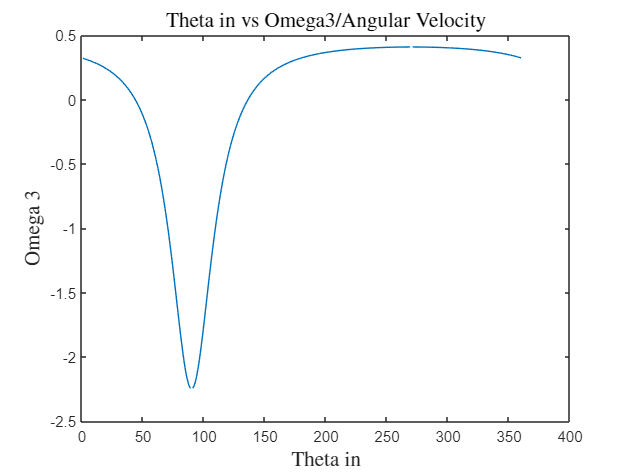

fig1v=figure();
    axis ([0 360 -3 3]); 
    plot(theta2,omega3)
    xlabel('Theta in ','Interpreter',"latex","FontSize",14)
    ylabel('Omega 3','Interpreter',"latex","FontSize",14)
    title('Theta in vs Omega3/Angular Velocity','Interpreter',"latex","FontSize",14)

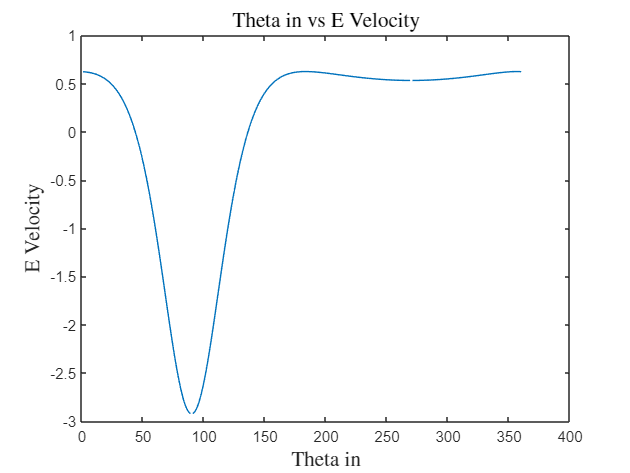

fig2v=figure();
    axis ([0 360 -3 3]); 
    plot(theta2,Vex)
    xlabel('Theta in ','Interpreter',"latex","FontSize",14)
    ylabel('E Velocity','Interpreter',"latex","FontSize",14)
    title('Theta in vs E Velocity','Interpreter',"latex","FontSize",14)

% Acceleration
for i = 1:360
    C = [cosd(theta3(i)),-b(i)*sind(theta3(i));
        sind(theta3(i)),b(i)*cosd(theta3(i))];
 
    D = [-a*alpha2*sind(theta2(i))-a*omega2^2*cosd(theta2(i))+2*bdot(i)*omega3(i)*sind(theta3(i))+b(i)*(omega3(i)^2)*cosd(theta3(i));
        a*alpha2*cosd(theta2(i))-a*omega2^2*sind(theta2(i))-2*bdot(i)*omega3(i)*cosd(theta3(i))+b(i)*(omega3(i)^2)*sind(theta3(i))];

    Y = C\D;

    bddot(i) = Y(1,1);
    alpha3(i) = Y(2,1);

    Aax = a*alpha2*sind(theta2(i))+a*(omega2^2)*cosd(theta2(i));
    Aay = -a*alpha2*cosd(theta2(i))+a*(omega2^2)*sind(theta2(i));

    Abx(i) = -bddot(i)*cosd(theta3(i))+2*bdot(i)*omega3(i)*sind(theta3(i))+b(i)*alpha3(i)*sind(theta3(i))+b(i)*(omega3(i)^2)*cosd(theta3(i));
    Aby(i) = -bddot(i)*sind(theta3(i))-2*bdot(i)*omega3(i)*cosd(theta3(i))-b(i)*alpha3(i)*cosd(theta3(i))+b(i)*(omega3(i)^2)*sind(theta3(i));

    dddot(i) = (-2*ddot(i)*omega3(i)*cosd(theta3(i))-d(i)*alpha3(i)*cosd(theta3(i))+d(i)*(omega3(i)^2)*sind(theta3(i)))/(sind(theta3(i)));
    eddot(i) = dddot(i)*cosd(theta3(i))-2*ddot(i)*omega3(i)*sind(theta3(i))-d(i)*alpha3(i)*sind(theta3(i))+d(i)*(omega3(i)^2)*cosd(theta3(i));

    Adx(i) = -dddot(i)*cos(theta3(i))+2*ddot(i)*omega3(i)*cosd(theta3(i))+d(i)*alpha3(i)*sind(theta3(i))+d(i)*(omega3(i)^2)*cosd(theta3(i));
    Ady(i) = 0;

    Aex(i) = eddot(i);
    Aey(i) = 0;
end

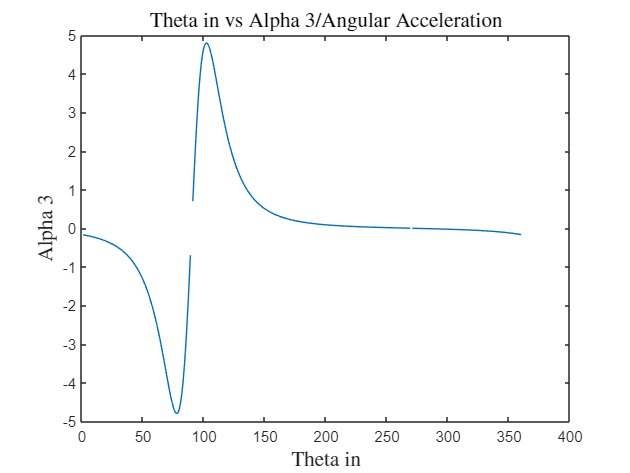

fig1A=figure();
    axis ([0 360 -3 3]); 
    plot(theta2,alpha3)
    xlabel('Theta in ','Interpreter',"latex","FontSize",14)
    ylabel('Alpha 3','Interpreter',"latex","FontSize",14)
    title('Theta in vs Alpha 3/Angular Acceleration','Interpreter',"latex","FontSize",14)

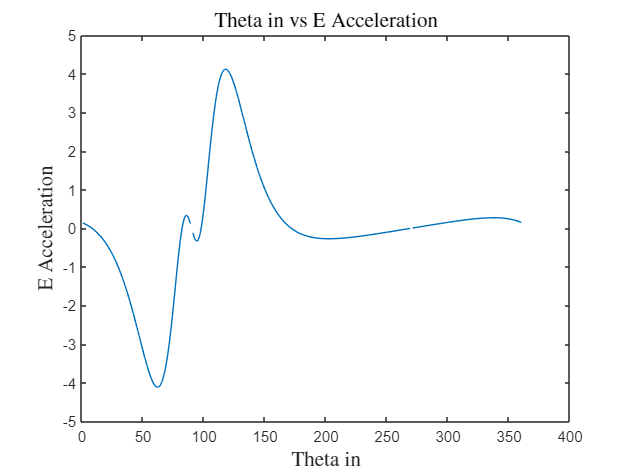

fig2A=figure();
    axis ([0 360 -3 3]); 
    plot(theta2,Aex)
    xlabel('Theta in ','Interpreter',"latex","FontSize",14)
    ylabel('E Acceleration','Interpreter',"latex","FontSize",14)
    title('Theta in vs E Acceleration','Interpreter',"latex","FontSize",14)

% Extra Credit
fig8 = figure();

for i=1:360

  %visu alize
    % 1. First plot the fix pivot at the center of global frame,  
    % and draw a dashed line parallel to X-axis for the slider line.
    % plot the slider axis
    plot([0 0],[-2 2],'k--',"LineWidth",1) 
    hold on
    axis equal; 
    xlim([-2 2]); ylim([-1.5 .5]);
    xlabel('$x$ (in)','Interpreter',"latex","FontSize",14)
    ylabel('$y$ (in)','Interpreter',"latex","FontSize",14)
    plot([0], [0],'ko',"LineWidth",2,'MarkerSize',6)
    plot([0], [-0.65],'ko',"LineWidth",2,'MarkerSize',6)
    % plot L2
    plot([0 Pax(i)],[-c Pay(i)],'b',"LineWidth",2)
    plot([0 Pdx(i)],[0 Pdy(i)],'c',"LineWidth",2)
    plot([0 Pbx(i)],[0 Pby(i)],'b',"LineWidth",2)
    plot([0 Pex(i)],[-f Pey(i)],'c',"LineWidth",2)
    %velocity&acceleration
    quiver(Pbx(i),Pby(i),Vbx(i),Vby(i),'g',"LineWidth",1.0)
    quiver(Pbx(i),Pby(i),Abx(i),Aby(i),'r',"LineWidth",1.0)
    quiver(Pex(i),Pey(i),Vex(i),0,'g',"LineWidth",1.0)
    quiver(Pex(i),Pey(i),Aex(i),0,'r',"LineWidth",1.0)
    title('Extra Credit(Red Arrow Acceleration,Green Velocity)','Interpreter',"latex","FontSize",14)
    



    frame(i)=getframe(fig8);
    hold off
end

 v1 = VideoWriter('slider.avi');
    open(v1)
    writeVideo(v1,frame);
    close(v1)